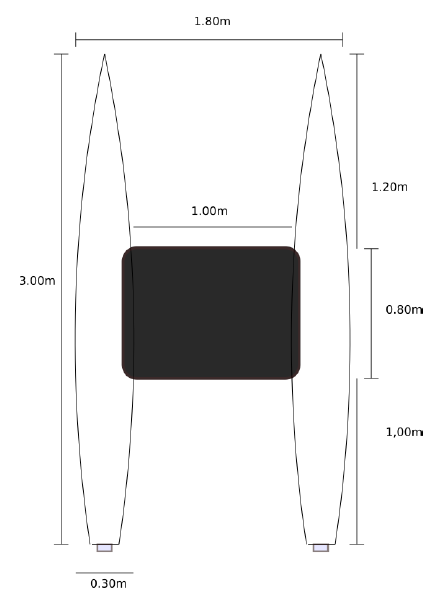

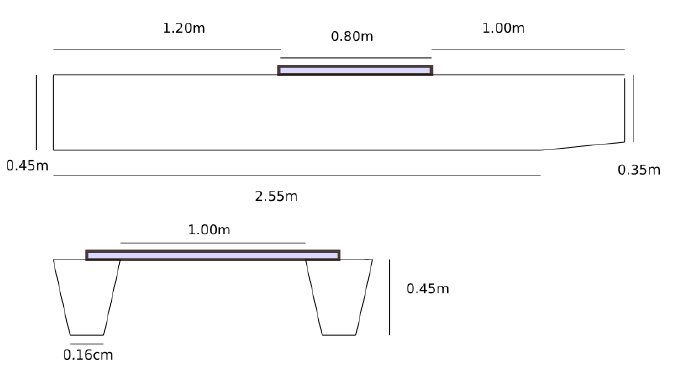

## Calculo de Inercia aproximada del edso-J

% Dimensiones y masa total
Casco1_dim = [3, 0.3, 0.45]; 
Casco2_dim = [3, 0.3, 0.45];
Center_dim = [0.80, 1, 0.01];
masa_total = 250; % Renombrado para mayor claridad

% Localización de cada parte respecto al bodyframe
Casco1_pos  = [0,  (0.15 + 0.5), 0]';
Casco2_pos  = [0, -(0.15 + 0.5), 0]';
central_pos = [0,             0, 0.45/2 + 0.01/2]';


%% --- CÁLCULO DE MASAS PARA CUERPO HOMOGÉNEO ---
% 1. Calcular volúmenes
vol_casco = Casco1_dim(1) * Casco1_dim(2) * Casco1_dim(3);
vol_centro = Center_dim(1) * Center_dim(2) * Center_dim(3);
vol_total = 2 * vol_casco + vol_centro;

% 2. Calcular la densidad constante
densidad = masa_total / vol_total; 

% 3. Asignar la masa a cada componente
%masa_casco1 = densidad * vol_casco;
%masa_casco2 = densidad * vol_casco;
%masa_centro = densidad * vol_centro;
A=0.3333; B=(1-A)/2;
masa_casco1 = masa_total * B;
masa_casco2 = masa_total * B;
masa_centro = masa_total * A;

%% --- CÁLCULO DE TENSORES ---
%% Calculo de tensor de inercia (sobre el CM de cada paralelepípedo)
inercia_casco1 = calcularTensorInercia(masa_casco1, Casco1_dim(1), Casco1_dim(2), Casco1_dim(3));
inercia_casco2 = calcularTensorInercia(masa_casco2, Casco2_dim(1), Casco2_dim(2), Casco2_dim(3));
inercia_centro = calcularTensorInercia(masa_centro, Center_dim(1), Center_dim(2), Center_dim(3));


%% Cambio de marco local a marco body usando teorema de Steiner
inercia_casco1_body = shiftInertiaTensor(inercia_casco1, masa_casco1, Casco1_pos);
inercia_casco2_body = shiftInertiaTensor(inercia_casco2, masa_casco2, Casco2_pos);
inercia_centro_body = shiftInertiaTensor(inercia_centro, masa_centro, central_pos);


%% Tensor de inercia total aproximado
inercia_total = inercia_casco1_body + inercia_casco2_body + inercia_centro_body;
disp('Tensor de inercia total para cuerpo homogéneo:');

Tensor de inercia total para cuerpo homogéneo:


disp(inercia_total);

   85.8352         0         0
         0  136.6715         0
         0         0  208.0643




%% Gráfico del catamarán
figure()
plotCuboidFromCenter(Casco1_pos, Casco1_dim); 
hold on; 
axis equal;
xlabel('X(m)'); 
ylabel('Y(m)'); 
zlabel('Z(m)');
title('Modelo Geométrico del Catamarán');
plotCuboidFromCenter(Casco2_pos, Casco2_dim);
plotCuboidFromCenter(central_pos, Center_dim);

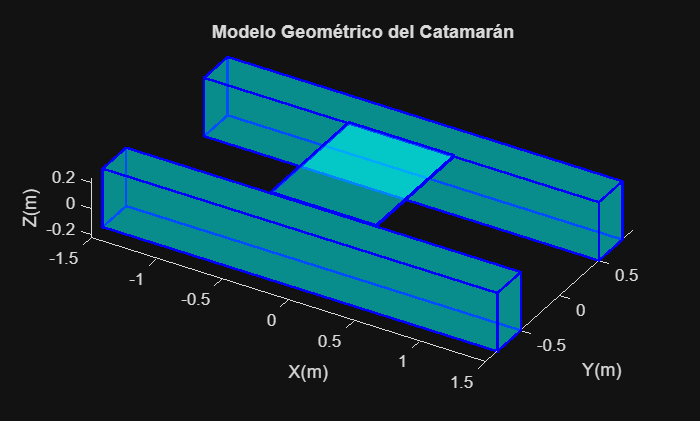

hold off;

## Calculo de coeficientes hidrodinamicos

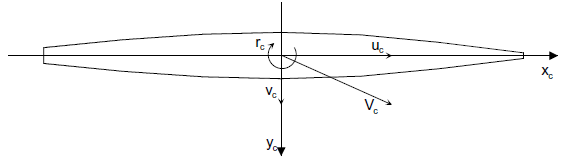

%--------------------------------------------------------------------------
% CÁLCULO DE COEFICIENTES HIDRODINÁMICOS PARA EL USV EDSON-J
%--------------------------------------------------------------------------
%
% DESCRIPCIÓN:
% Este script de MATLAB calcula los coeficientes hidrodinámicos para el modelo
% de maniobra del Vehículo de Superficie No Tripulado (USV) EDSON-J[cite: 80].
% El EDSON-J es un vehículo de doble casco (catamarán) desarrollado en la
% Universidad Nacional de San Agustín de Arequipa[cite: 30].
%
% Los cálculos se basan en métodos analíticos y empíricos mencionados en la
% tesis "SISTEMA DE CONTROL LPV/H∞ PARA UN VEHÍCULO ACUÁTICO NO TRIPULADO".
% Estos coeficientes son esenciales para simular la dinámica del vehículo
% y para el diseño de su sistema de control[cite: 349].
%
% AUTOR: EDUARDO RODRIGUEZ CANALES [cite: 7]
% INSTITUCIÓN: UNIVERSIDAD NACIONAL DE SAN AGUSTIN DE AREQUIPA [cite: 1]
%
%--------------------------------------------------------------------------

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1. PARÁMETROS PRINCIPALES DEL VEHÍCULO
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Definición de las características físicas y geométricas del USV EDSON-J.
% Estos valores se corresponden con la Tabla 2.1 y Tabla A.1 de la tesis[cite: 185, 2234].

% Parámetros físicos
m = 250;      % Masa del vehículo en kg (sin carga útil)[cite: 186].
mp = 300;     % Masa de operación, incluye una carga útil de 50 kg[cite: 186].
p = 1024;     % Densidad del fluido (agua de mar) en kg/m^3[cite: 425].

% Parámetros geométricos
L = 3;        % Eslora (longitud) total del vehículo en metros[cite: 186].
W = 1.8;      % Manga (ancho) total del vehículo en metros[cite: 186].
D = 0.3;      % Manga de uno de los cascos (hull breadth) en metros[cite: 186].
T = 0.16;     % Calado (draft) del vehículo en metros[cite: 186].
xg = 0.08;    % Posición longitudinal del centro de masa (CoG)[cite: 2264]. [cite_start]La tesis reporta 0.11 m en Apéndice A[cite: 2234].
a = 0.03;     % Coeficiente de forma del casco[cite: 2264].

% Parámetros de operación y de inercia
U = 1.5;      % Velocidad de avance de crucero para la linealización en m/s[cite: 160].
u0 = 1.5;     % Velocidad de avance de crucero (surge velocity)[cite: 2264].
rg = 0.3 * L; % Radio de giro estimado[cite: 326].
Ir = (0.5 * m) * rg^2; % Momento de inercia estimado (Ecuación 2.18)[cite: 324].
Iz = (0.5 * m) * xg^2 + Ir; % Momento de inercia en el eje z para un casco (Ecuación 2.17)[cite: 321].
Iz = 2 * Iz;  % Momento de inercia total para ambos cascos (twin hull).

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2. CÁLCULO DE MASAS AÑADIDAS (ADDED MASS)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Las masas añadidas representan la inercia adicional debido al agua que es
% acelerada por el vehículo. [cite_start]Se calculan usando la "strip theory"[cite: 428].
syms x;       % Variable simbólica para la integración a lo largo de la eslora del casco.

% Coeficiente de masa añadida para una elipse (Ecuación 2.30)[cite: 413, 415].
ma = pi * p * (T^2 / 2);

% Términos de masa añadida. Las integrales representan la distribución a lo largo de un casco.
Xudot = ((-4 * a * p * pi) / 3) * (L/2) * (T/2)^2; % Masa añadida axial (Ecuación 2.31)[cite: 423].
Yvdot = -ma * int(x^0, [0 L]);                     % Masa añadida en sway, Y_v_dot (Ecuación 2.32)[cite: 430].
Yrdot = -ma * int(x, [0 L]);                       % Acoplamiento masa añadida sway-yaw, Y_r_dot (Ecuación 2.33)[cite: 432].
Nrdot = -ma * int(x^2, [0 L]);                     % Masa añadida en yaw, N_r_dot (Ecuación 2.34)[cite: 434].
Nvdot = Yrdot;                                     % Término acoplamiento N_v_dot = Y_r_dot (Ecuación 2.33)[cite: 432].

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3. CÁLCULO DE ARRASTRES (DRAG)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% El arrastre es la fuerza de resistencia del agua. Se divide en componentes lineales y cuadráticos.

%---------- Arrastros Cuadráticos (Amortiguamiento no lineal) -------------
Af = pi * T * D/2;   % Área frontal estimada.
Ap = L * T;      % Área de perfil estimada.
Cd = 0.004 * pi * (Ap/Af) * ((1 + (60 * ((T/L)^3)) + 0.0025 * (L/T))); % Coeficiente de arrastre.
Db = -0.5 * p * Af * Cd * U^2; % Fuerza de arrastre base.

% Coeficientes de arrastre cuadrático.
Xuu = -7.7608;                                  % Arrastre cuadrático en surge, X_|u|u (Sección 2.4.1)[cite: 396].
Yvv = -0.5 * p * (Cd * T * int(x^0, [0 L]));    % Arrastre cuadrático en sway, Y_|v|v (Ecuación 2.26)[cite: 402].
Nvv = -0.5 * p * (Cd * T * int(x^1, [0 L]));    % Acoplamiento de arrastre cuadrático sway-yaw.
Yrr = -0.5 * p * (Cd * T * int(x^2, [0 L]));    % Acoplamiento de arrastre cuadrático yaw-sway.
Nrr = -0.5 * p * (Cd * T * int(x^2 * abs(x), [0 L])); % Arrastre cuadrático en yaw, N_|r|r (Ecuación 2.27)[cite: 404].

%---------------- Arrastros Lineales (Amortiguamiento lineal) --------------
Xu = -0.1456;                                  % Arrastre lineal en surge, X_u (Sección 2.4.1)[cite: 396].
Yv = -U * ma;                                  % Arrastre lineal en sway, Y_v (Ecuación 2.28)[cite: 406, 408].
Nr = -U * L/2 * ma - U * ma * int(x, [0 L]);   % Arrastre lineal en yaw, N_r (Ecuación 2.29)[cite: 407, 409].

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4. FUERZAS Y MOMENTOS DE LAS HÉLICES
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Coeficientes que modelan el efecto de los propulsores[cite: 453].
% Se basan en la serie B de Wageningen y sus valores finales se listan en la Tabla 2.7[cite: 561].
% La relación principal de fuerzas se da en la Ecuación 2.41[cite: 536].

Xuuh = -6.0523; % X_uu^h en Tabla 2.7[cite: 562].
Xunh = -1.8411; % X_un^h en Tabla 2.7[cite: 562].
Xnnh = 0.5259;  % X_nn^h en Tabla 2.7[cite: 562].
Yuvh = 0.1910;  % Y_uv^h en Tabla 2.7[cite: 562].
Yvnh = -0.1794; % Y_vn^h en Tabla 2.7[cite: 562].
Nurh = 0.0387;  % N_ur^h en Tabla 2.7[cite: 562].
Nrnh = 0.0118;  % N_rn^h en Tabla 2.7[cite: 562].

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 5. COEFICIENTES HIDRODINÁMICOS TOTALES PARA EL MODELO
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Unificación de los coeficientes para el modelo twin-hull[cite: 617].
% Las siguientes fórmulas son la implementación de la Ecuación 2.56 [cite: 665] de la tesis.

% Coordenadas de las hélices
yh = 0.75; % Distancia lateral de las hélices al eje central (Tabla 2.9)[cite: 631].
xh = 1.5;  % Posición longitudinal de las hélices (Tabla 2.9)[cite: 631].

%--- Coeficientes para la ecuación de SURGE (eje x) ---
Xudot = 2 * Xudot;
Xu = 2 * Xu;
Xuu = 2 * Xuu + 2 * Xuuh;
Xunc = 2 * Xunh;
Xrnd = -2 * Xunh * yh;
Xncnc = 2 * Xnnh;
Xndnd = 2 * Xnnh;

%--- Coeficientes para la ecuación de SWAY (eje y) ---
Yvdot = 2 * Yvdot;
Yrdot = 2 * Yrdot;
Yv = 2 * Yv;
Yvv = 2 * Yvv;
Yvnc = 2 * Yvnh;
Yrnc = 2 * Yvnh * xh;

%--- Coeficientes para la ecuación de YAW (eje z) ---
Nrdot = 2 * Nrdot + 2 * Yvdot * xg^2;
Nvdot = 2 * Nvdot;
Nr = 2 * Nr;
Nrr = 2 * Nrr;
Nund = -2 * Xunh * yh;
Nrnc = 2 * Nrnh + 2 * Xunh * yh^2 + 2 * Yvnh * xh^2;
Nncnd = -4 * Xnnh * yh;
Nvnc = 2 * Yvnh * xh;

Graficos

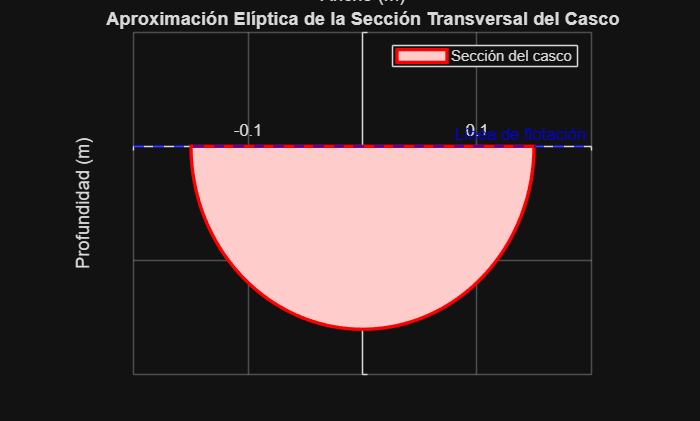

% APROXIMACIÓN ELÍPTICA DE LA SECCIÓN TRANSVERSAL DEL CASCO EDSON-J

% --- Parámetros del casco del EDSON-J (de la Tabla 2.1 de la tesis) ---
ancho_maximo_casco = 0.30;  % metros
calado = 0.16;              % metros (profundidad sumergida)

% --- Cálculo de los semiejes de la elipse ---
% El semieje horizontal (a) es la mitad del ancho máximo.
semi_eje_horizontal = ancho_maximo_casco / 2;

% El semieje vertical (b) es el calado, ya que representa la profundidad.
semi_eje_vertical = calado;

% --- Generar los puntos para graficar la parte sumergida de la elipse ---
% Usamos un rango de ángulos de pi a 2*pi para dibujar solo la mitad inferior.
theta = linspace(pi, 2*pi, 200);

% Ecuaciones paramétricas de la elipse
x = semi_eje_horizontal * cos(theta);
y = semi_eje_vertical * sin(theta);

% --- Crear la gráfica ---
figure;  % Crea una nueva ventana de figura
hold on; % Permite dibujar múltiples elementos en la misma gráfica

% Dibujar y rellenar la sección del casco
h_casco = fill(x, y, [1 0.8 0.8], 'EdgeColor', 'red', 'LineWidth', 2);

% Dibujar la línea de flotación (waterline) en y=0
h_linea = yline(0, '--b', 'Línea de flotación', 'LineWidth', 1.5);

% --- Añadir etiquetas, título y formato ---
title('Aproximación Elíptica de la Sección Transversal del Casco');
xlabel('Ancho (m)');
ylabel('Profundidad (m)');
grid on;
ax = gca; % Obtener el manejador de los ejes actuales
ax.XAxisLocation = 'origin'; % Centrar el eje Y en x=0
ax.YAxisLocation = 'origin'; % Centrar el eje X en y=0

% --- Ajustar la escala y la leyenda ---
axis equal; % Asegura que la elipse no se vea distorsionada por la escala de los ejes
ylim([-0.2 0.1]); % Ajusta los límites del eje Y para una mejor visualización
xlim([-0.2 0.2]); % Ajusta los límites del eje X
legend([h_casco], {'Sección del casco'});
hold off; % Finaliza el modo de dibujo múltiple

Area longitudinal

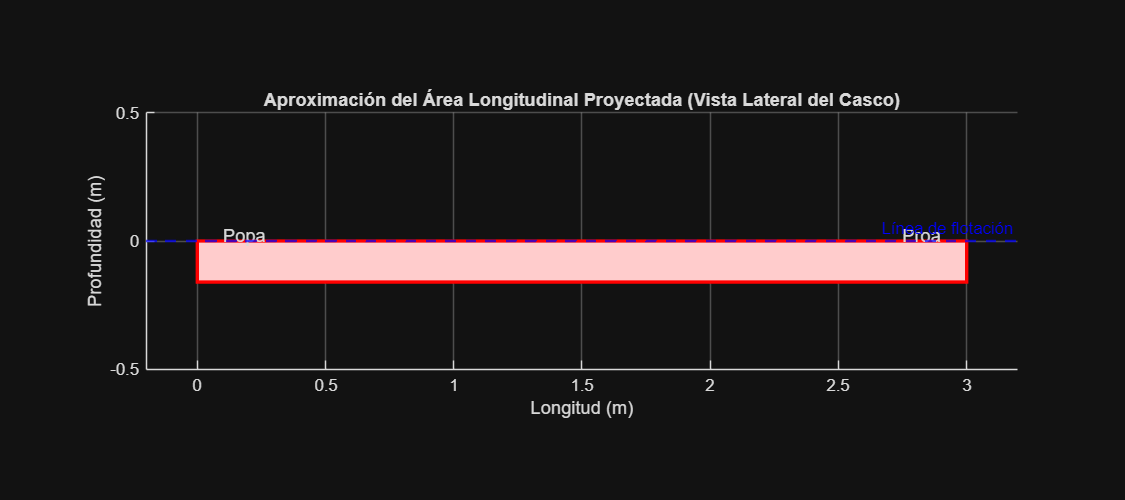

% APROXIMACIÓN DEL ÁREA LONGITUDINAL PROYECTADA DEL CASCO EDSON-J

% --- Parámetros del casco (de la Tabla 2.1 de la tesis) ---
longitud = 3.0;  % metros
calado = 0.16;   % metros (profundidad sumergida)

% --- Crear la gráfica ---
figure('Position', [100, 100, 900, 400]); % Crea una figura con tamaño panorámico
ax = gca; % Obtiene los ejes actuales
hold on; % Permite dibujar múltiples elementos en la misma gráfica

% --- Dibujar los elementos ---
% Dibuja el rectángulo que representa el área longitudinal sumergida
% La función rectangle tiene la forma: rectangle('Position', [x_inicio, y_inicio, ancho, alto])
h_rect = rectangle('Position', [0, -calado, longitud, calado], ...
                   'FaceColor', [1 0.8 0.8], ... % Color de relleno verde claro
                   'EdgeColor', 'red', ...
                   'LineWidth', 2);

% Dibuja la línea de flotación (waterline) en y=0
h_linea = yline(0, '--b', 'Línea de flotación', 'LineWidth', 1.5);

% --- Añadir etiquetas y título ---
title('Aproximación del Área Longitudinal Proyectada (Vista Lateral del Casco)');
xlabel('Longitud (m)');
ylabel('Profundidad (m)');
grid on;

% Añadir texto para identificar la proa (bow) y la popa (stern)
text(longitud - 0.1, 0.02, 'Proa', 'HorizontalAlignment', 'right', 'FontSize', 11);
text(0.1, 0.02, 'Popa', 'HorizontalAlignment', 'left', 'FontSize', 11);

% --- Ajustar la escala y los límites para una mejor visualización ---
axis equal; % Mantiene la proporción correcta para que no se deforme la vista
xlim([-0.2, longitud + 0.2]);
ylim([-0.5, 0.5]);

hold off; % Finaliza el modo para añadir más elementos a la gráfica

Error using legend (line 245)
One or more of the specified objects can not be included in a legend.


function I = calcularTensorInercia(masa, a, b, c)
% calcularTensorInercia - Calcula el tensor de inercia de un paralelepípedo.
%
% Sintaxis: I = calcularTensorInercia(masa, a, b, c)
%
% Entradas:
%   masa - La masa total del paralelepípedo (ej. en kg).
%   a    - La longitud total a lo largo del eje x (ej. en m).
%   b    - La longitud total a lo largo del eje y (ej. en m).
%   c    - La longitud total a lo largo del eje z (ej. en m).
%
% Salidas:
%   I    - El tensor de inercia de 3x3 [Ixx, 0, 0; 0, Iyy, 0; 0, 0, Izz].

% Calcular los momentos de inercia en la diagonal
I_xx = (1/12) * masa * (b^2 + c^2);
I_yy = (1/12) * masa * (a^2 + c^2);
I_zz = (1/12) * masa * (a^2 + b^2);

% Los productos de inercia (fuera de la diagonal) son cero porque
% los ejes están alineados con los ejes de simetría del cuerpo.

% Crear el tensor de inercia (matriz diagonal)
I = [I_xx,  0,    0;
       0,  I_yy,   0;
       0,    0,  I_zz];

end

function plotCuboidFromCenter(centro, dimensiones)
% plotCuboidFromCenter - Grafica un cuboide 3D a partir de su centro.
%
% Sintaxis: plotCuboidFromCenter(centro, dimensiones)
%
% Entradas:
%   centro      - Vector 1x3 [cx, cy, cz] que define el centro geométrico.
%   dimensiones - Vector 1x3 [a, b, c] con el largo total, ancho y alto.

% Extraer coordenadas del centro y dimensiones
cx = centro(1);
cy = centro(2);
cz = centro(3);
a = dimensiones(1); % Largo total en x
b = dimensiones(2); % Ancho total en y
c = dimensiones(3); % Alto total en z

% Calcular las posiciones de los 8 vértices relativos al centro
% Se resta y suma la mitad de cada dimensión desde el centro
vertices = [cx - a/2, cy - b/2, cz - c/2; % Vértice 1
            cx + a/2, cy - b/2, cz - c/2; % Vértice 2
            cx + a/2, cy + b/2, cz - c/2; % Vértice 3
            cx - a/2, cy + b/2, cz - c/2; % Vértice 4
            cx - a/2, cy - b/2, cz + c/2; % Vértice 5
            cx + a/2, cy - b/2, cz + c/2; % Vértice 6
            cx + a/2, cy + b/2, cz + c/2; % Vértice 7
            cx - a/2, cy + b/2, cz + c/2];    % Vértice 8

% La definición de las caras no cambia, ya que solo conectan los índices
% de los vértices, sin importar dónde estén ubicados.
faces = [1, 2, 3, 4; % Cara inferior
         5, 6, 7, 8; % Cara superior
         1, 2, 6, 5; % Cara frontal
         4, 3, 7, 8; % Cara trasera
         1, 4, 8, 5; % Cara izquierda
         2, 3, 7, 6];% Cara derecha

% Usar la función patch para dibujar el cuboide
patch('Vertices', vertices, 'Faces', faces, ...
      'FaceColor', 'cyan', ...       % Color de las caras
      'FaceAlpha', 0.3, ...          % Transparencia de las caras
      'EdgeColor', 'blue', ...       % Color de las aristas
      'LineWidth', 1.5);             % Grosor de las aristas

end


function I_new = shiftInertiaTensor(I_cm, masa, d)
% shiftInertiaTensor - Cambia el origen del tensor de inercia usando el Teorema de Ejes Paralelos.
%
% Sintaxis: I_new = shiftInertiaTensor(I_cm, masa, d)
%
% Entradas:
%   I_cm - El tensor de inercia original 3x3, calculado respecto al centro de masa.
%   masa - La masa total del objeto.
%   d    - El vector de desplazamiento 3x1 [dx; dy; dz] desde el NUEVO origen
%          hasta el ANTIGUO origen (el centro de masa).
%
% Salidas:
%   I_new - El nuevo tensor de inercia 3x3, calculado respecto al nuevo origen.

% Asegurarse de que 'd' es un vector columna para las operaciones matriciales
if isrow(d)
    d = d';
end

% Calcular el término de corrección del Teorema de Ejes Paralelos
% I_shift = M * [ (d'·d)·I - (d ⊗ d) ]
% Donde d'·d es el producto punto y d*d' es el producto exterior (tensorial)
dot_product_d = d' * d; % Magnitud al cuadrado (escalar)
outer_product_d = d * d'; % Matriz 3x3

I_shift = masa * ( dot_product_d * eye(3) - outer_product_d );

% El nuevo tensor de inercia es la suma del tensor original y el término de corrección
I_new = I_cm + I_shift;

end

